## MAS416 - Tutorial 5 - Problem 1

#### RLC circuit with DC voltage source

clc; clear all; close all;

R = 20; % Ohm
L = 4; % Henry
C = 2.5*10^-3; % Farad

U_min = 0; % V
U_max = 12; % V

simTime = 3; % s
rampTime = 0.5; % s

iL = 0; % Inductor current, state variable
uC = 0; % Capacitor voltage, state variable

t = 0;
idx = 1;
dt = 10^-4;

while t <= simTime

    % uA is the voltage between DC supply and R
    if t <= rampTime
        uA = U_max * t/rampTime;
    else
        uA = U_max;
    end
    
    % uB is the voltage between R and L (resistor and inductor)
    uB = uA-iL*R;

    % Change in current in the inductor L
    iLDot = 1/L * (uB-uC);

    % Change in voltage in the capacitor C
    uCDot = 1/C * iL;

    % Logging
    t_plot(idx) = t;
    iL_plot(idx) = iL;
    uA_plot(idx) = uA;
    uB_plot(idx) = uB;
    uC_plot(idx) = uC;
    uR_plot(idx) = uA-uB;
    uL_plot(idx) = uB-uC;

    % Time integrating
    iL = iL + iLDot * dt;
    uC = uC + uCDot * dt;

    % Increase time and index
    t = t + dt;
    idx = idx + 1;
end

plot(t_plot, iL_plot, 'LineWidth', 2)
grid

#### RLC circuit with AC voltage source

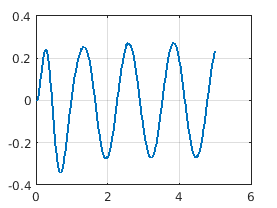

clc; clear all; close all;

R = 20; % Ohm
L = 4; % Henry
C = 2.5*10^-3; % Farad

U_max = 12; % V

omega = [5 10 15]; % rad/s

simTime = 5; % s
rampTime = 0.5; % s

iL = 0; % Inductor current, state variable
uC = 0; % Capacitor voltage, state variable

t = 0;
idx = 1;
dt = 10^-2;

round = 1;

while t <= simTime
    if(round == 1)
    uA = U_max * sqrt(2) * sin(omega(1) * t);
    
    % uB is the voltage between R and L (resistor and inductor)
    uB = uA-iL*R;

    % Change in current in the inductor L
    iLDot = 1/L * (uB-uC);

    % Change in voltage in the capacitor C
    uCDot = 1/C * iL;

    % Logging
    t_plot_round_1(idx) = t;
    iL_plot_round_1(idx) = iL;

    % Time integrating
    iL = iL + iLDot * dt;
    uC = uC + uCDot * dt;

    % Increase time and index
    t = t + dt;
    idx = idx + 1;
    
    if(t >= simTime - 2*dt)
        t = 0;
        round = 2;
        idx = 1;
        iL = 0;
        uC = 0;
        t_plot = 0;
    end
    elseif(round == 2)
    uA = U_max * sqrt(2) * sin(omega(2) * t);
    
    % uB is the voltage between R and L (resistor and inductor)
    uB = uA-iL*R;

    % Change in current in the inductor L
    iLDot = 1/L * (uB-uC);

    % Change in voltage in the capacitor C
    uCDot = 1/C * iL;

    % Logging
    t_plot_round_2(idx) = t;
    iL_plot_round_2(idx) = iL;

    % Time integrating
    iL = iL + iLDot * dt;
    uC = uC + uCDot * dt;

    % Increase time and index
    t = t + dt;
    idx = idx + 1;

    if(t >= simTime - 2*dt)
    t = 0;
    round = 3;
    idx = 1;
    iL = 0;
    uC = 0;
    t_plot = 0;
    end
    else
    uA = U_max * sqrt(2) * sin(omega(3) * t);
    
    % uB is the voltage between R and L (resistor and inductor)
    uB = uA-iL*R;

    % Change in current in the inductor L
    iLDot = 1/L * (uB-uC);

    % Change in voltage in the capacitor C
    uCDot = 1/C * iL;

    % Logging
    t_plot_round_3(idx) = t;
    iL_plot_round_3(idx) = iL;

    % Time integrating
    iL = iL + iLDot * dt;
    uC = uC + uCDot * dt;

    % Increase time and index
    t = t + dt;
    idx = idx + 1;
    end
end
plot(t_plot_round_1, iL_plot_round_1, 'LineWidth', 2)
grid

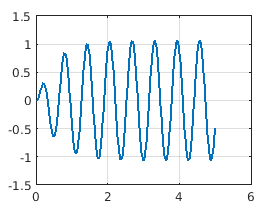

plot(t_plot_round_2, iL_plot_round_2, 'LineWidth', 2)
grid

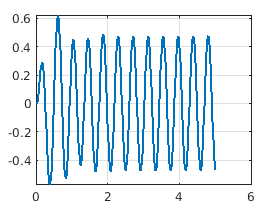

plot(t_plot_round_3, iL_plot_round_3, 'LineWidth', 2)
grid